# A Brief introduction to MatLab

Si necesitan mandarme algún mail:

ulises.bussi@unq.edu.ar                 <-- the institutional one

ulisesbussi@gmail.com                   <-- personal one (i'd rather that you write here, because i don't check the institutional every day)

En este **notebook** vamos a hacer una pequeña introducción a Matlab.

En lo que respecta al tipo de variables hay varios tipos y entrar en detalle de todos, sería imposible. por lo que esto no es más que un surface scratch:

-  Bool: un booleano es una variable que puede tomar el valor verdadero ('true') or falso ('false')

- Número : las variables numéricas tienen distintos subtipos (enteros, float, complejos).

- Str: un string de caractéres.

- Arrays: son vectores, matrices, hiper-matrices .

- Cells : son como arrays con la capacidad de tener tipos mezclados.

- Struct: es un objeto, que permite tener campos adentro que pueden tener cualquier tipo de variables e incluso funciones....


boolVar = true;
myPrint(boolVar)

Soy una variable logical, y mi valor es: 
   1




floatVar=3.44;
myPrint(floatVar)

Soy una variable double, y mi valor es: 
    3.4400





strVar = 'Hola!';
myPrint(strVar)

Soy una variable char, y mi valor es: 
Hola!



arrayVar = [1,2,3,4];
myPrint(arrayVar)

Soy una variable double, y mi valor es: 
     1     2     3     4



cellVar = {'sopa', 'carne', 'eggs', 6, strVar};
myPrint(cellVar)

Soy una variable cell, y mi valor es: 
    'sopa'    'carne'    'eggs'    [6]    'Hola!'



%en matlab todo tipo de array celdas estructuras arrancan en el índice 1 y se usan paréntesis para acceder ()
disp('mi primer elemento tiene el índice 1, y su valor es:'),disp ( cellVar(1))

mi primer elemento tiene el índice 1, y su valor es:
    'sopa'




structVar = struct('identificator1', 33, 'aList',{cellVar},'cats', 'are Awesome!');
myPrint(structVar)

Soy una variable struct, y mi valor es: 
    identificator1: 33
             aList: {'sopa'  'carne'  'eggs'  [6]  'Hola!'}
              cats: 'are Awesome!'





disp('Tengo campos como identificador y estos son:'),disp(fieldnames(structVar))

Tengo campos como identificador y estos son:
    'identificator1'
    'aList'
    'cats'



%Para acceder a los campos podemos hacer struct.identificador
structVar.cats

ans = 'are Awesome!'

%se pueden agregar campos dinámicamente, por ejemplo después de creada la estructura agregarle un campo que contenga una funcion
structVar.unaFuncion  = @(x) x^2; %calcula el cuadrado de un número

structVar.unaFuncion(3)

ans = 9

Hagamos un poco de matemática...

a = 3;
b = 4;
%suma, restas, multiplicaciones, divisiones, potencias, raices

suma = a+b;
resta = a-b;
producto = a*b;
division = a/b;
potencia = a^b;

funAux2 = @(nombre,val) string(string(nombre)+': '+string(val));
funAux= @(var) strcat(inputname(1),':','  ',string(var));
disp([funAux(suma), ...
      funAux(resta),...
      funAux(producto),...
      funAux(division),...
      funAux(potencia)]');

    "suma:7"
    "resta:-1"
    "producto:12"
    "division:0.75"
    "potencia:81"




%podemos hacer comparaciones
disp(['a=3 , b=4',...
      funAux2('a>b (a mayor que b)',a>b),...
      funAux2('a<b (a menor que b)',a<b),...
      funAux2('a==b (a igual que b)',a==b),...
      funAux2('a~=b (a distinto de b)',a~=b)]')

    "a=3 , b=4"
    "a>b (a mayor que b): false"
    "a<b (a menor que b): true"
    "a==b (a igual que b): false"
    "a~=b (a distinto de b): true"



% algunas otras operaciones
piso = floor(3.1415);
techo = ceil(3.1415);
redondeo = round(3.1415);
restoDivision = mod(27,6);
valorAbsoluto = abs(-7);
maximo =max(5,6);  %se puede aplicar a un vector en general, o matrices
minimo = min(5,6);

disp([funAux(piso),...
    funAux(techo),...
    funAux(redondeo),...
    funAux(restoDivision),...
    funAux(valorAbsoluto),...
    funAux(maximo),...
    funAux(minimo)]')

    "piso:3"
    "techo:4"
    "redondeo:3"
    "restoDivision:3"
    "valorAbsoluto:7"
    "maximo:6"
    "minimo:5"



%Operaciones con complejos
(3+2j) * (3+2i)

ans =    5.0000 +12.0000i


# Control de Flujo

Ahora vamos a ver un poco como manejar el control de flujo en los algorimos.

# if

Empecemos con el if, esta condición de manejo de flujo ejecuta un bloque de código si se cumple la condición dada (en general se considera que la condición no se cumple si el valor de la variable u operación a evaluar es 0 y si se cumple en otros casos). uno puede utilizar una comparación lógica o simplemente una variable para el if.  Adicionalmente uno puede colocar comparaciones adicionales dentro del mismo comando ( utilizando **'elseif'** ), agregar un bloque para ejecutar en una condición por defecto **'else**'. Para indicar el final del bloque se utiliza un **'end'**.

pueden usarse:

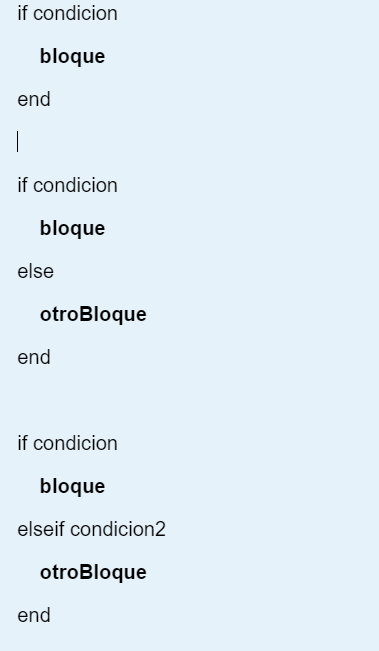                              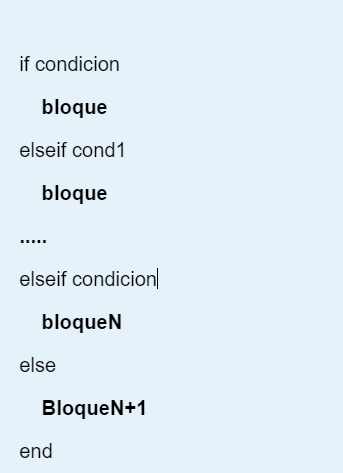

Algunos ejemplos

a = 57 ;
b = 50;

if a>b
  disp([a, 'es mayor que',b])
  a =a- 35
  %Un montón de otras líneas de código
elseif a< 1
  disp('else-if condition')
else
  disp('else condition')  
end

9es mayor que2


a = 22

if a>b
  disp([a, 'is greater than ',b])
  a = a+ 35;
else
  disp([' ', a, ' is smaller than ',b])  
end

  is smaller than 2


 Si es necesario combinar diferentes pruebas podemos usar los operaderos como en C++:

mayor **>** , mayor igual **>=**

menor **< **, menos igual **<=**

igual **==**

and **&, **or **|**, exor  **xor**, not **~**

# 'for'

---

Funciona muy parecido en todos los lenguajes, solo cambia la sintaxis, para armar un for:

for iterador = arrayConElementos

**    bloqueAEjecutar**

end

el array con elementos, puede ser creado de la forma clásica (como se vió más arriba) o con un pequeño atajo propio de matlab:

**inicio:paso:fin **o **inicio:fin **(si el paso es 1)

Veamos algunos ejemplos:

vector = {1,7,5,'pez'};
for i=vector  
  disp(i)
end

    [1]

    [7]

    [5]

    'pez'



inicio=0; paso= 0.5; fin=3;
for i= inicio:paso:fin %también se puede usar for i = 0:0.5:3
  disp(i)
end

     0

    0.5000

     1

    1.5000

     2

    2.5000

     3



Algunas operaciones más complejas:

array1 =  [1,2,3] ; 
array2 =  [1,2,1];

myPrint(array1)

Soy una variable double, y mi valor es: 
     1     2     3



disp(['mi forma es :']), disp(size(array1))

mi forma es :
     1     3



array1+array2  

ans =      2     4     4


array1-array2

ans =      0     0     2


array1.*array2 %elementWise Operation

ans =      1     4     3


array1./array2 %elementwise

ans =      1     1     3


array1*(array2') %traspongo el segundo elemento usando ' y hago un producto escalar

ans = 8

mat = [1,2,3; 1 0 0; 0 0 1]; %creo una matriz
mat*array1' %producto matriz vector

ans =     14
     1
     3


nDimMat =randn(2,3,3) %matriz multidimencional

nDimMat = nDimMat(:,:,1) =

    1.3993   -0.9225    0.5880
   -0.8799    2.3144   -0.3098


nDimMat(:,:,2) =

   -1.0330    0.3421   -0.9033
    1.1034   -2.2640    2.9700


nDimMat(:,:,3) =

   -0.0118   -0.8880    0.6946
   -1.9995   -0.4199   -0.1628


size(nDimMat) % forma de la hiper-matriz

ans =      2     3     3


# Plots

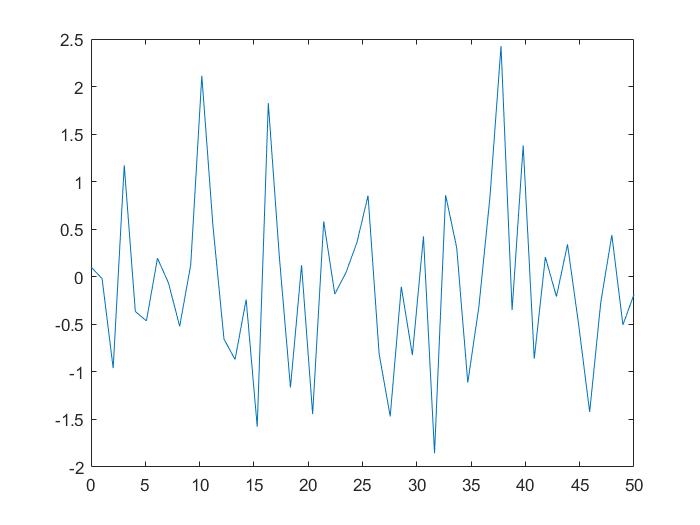

x = linspace(0,50,50);
y = randn(50,1);
figure(1)
plot(x,y)

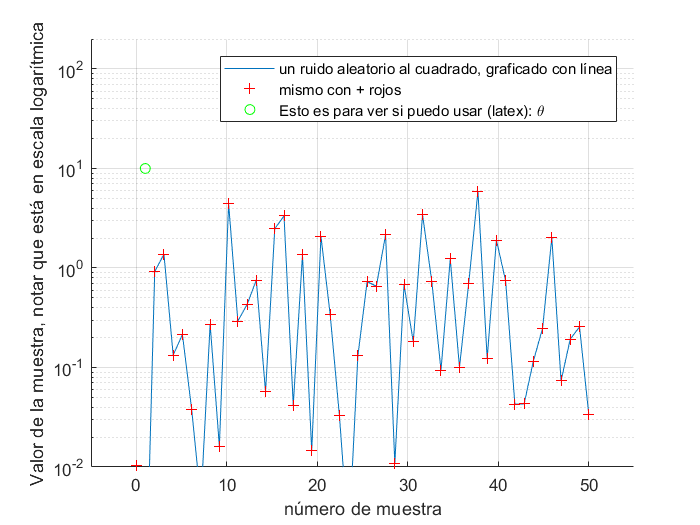

labelWithLatex = 'Esto es para ver si puedo usar (latex): \theta ';
 
figure(2);
ax = gca();
hold on ;% <- si queremos agregar más plots a la misma figura
plot(x,y.^2);
plot(x,y.^2,'r+');
plot(1,10,'go');
label1 ='un ruido aleatorio al cuadrado, graficado con línea';
label2='mismo con + rojos';
legend( label1,label2,labelWithLatex)
xlim([-5,55])
ylim([0.01, 200])
ax.YScale='log'; %escala logaritmica

xlabel('número de muestra')
ylabel('Valor de la muestra, notar que está en escala logarítmica')
grid on

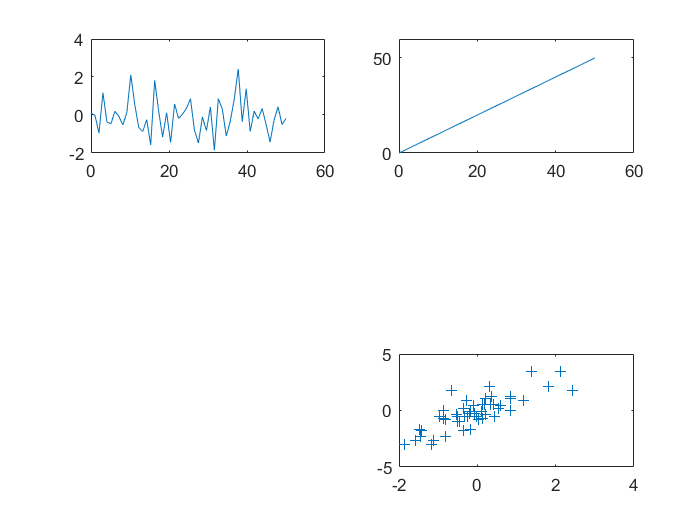

%para hacer varios sub-plots
figure(3)
ncols = 3;
nrows = 2;
index = 1;
subplot(ncols,nrows,index)
plot(x,y)
subplot(3,2,2)
plot(x,x)
subplot(3,2,6)
plot(y,y+y(end:-1:1),'+')

# Funciones

En esta parte una pequeña introducción a funciones en matlab. hay dos maneras de crear funciones.

la primera, la clásica, es una definición explícita:

function variablesDeRetorno =myPrint(var)

    bloqueDeCodigo

end

hacerAlgoConLaVariable = @(x) (x+5)^2;

la segunda es la creación de funciones en línea:

unaFuncionNueva = @(variable) hacerAlgoConLaVariable(variable);
unaFuncionNueva(3)

ans = 64

Si se crea de manera explícita debe estar al final del script o en un archivo a parte que tenga el mismo nombre que la función.


function myPrint(var)
   disp(['Soy una variable ' , class(var) ,', y mi valor es: '])
   disp(var)
end
